Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

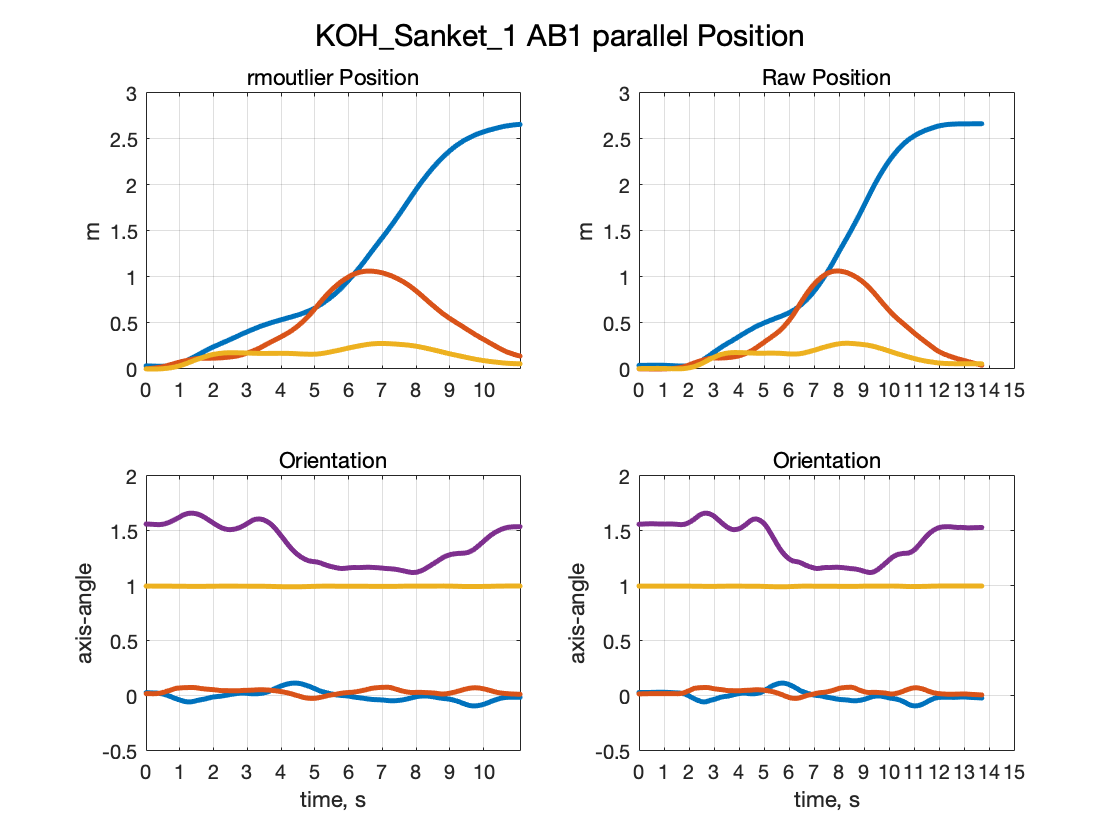

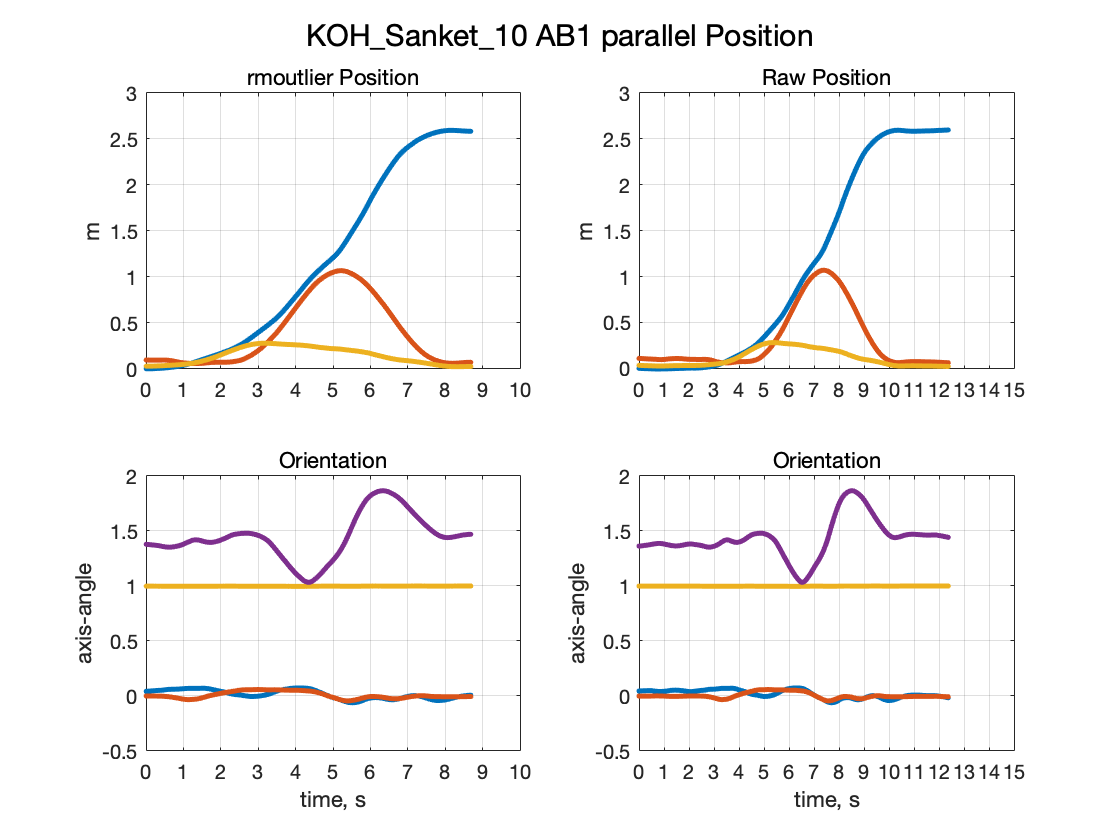

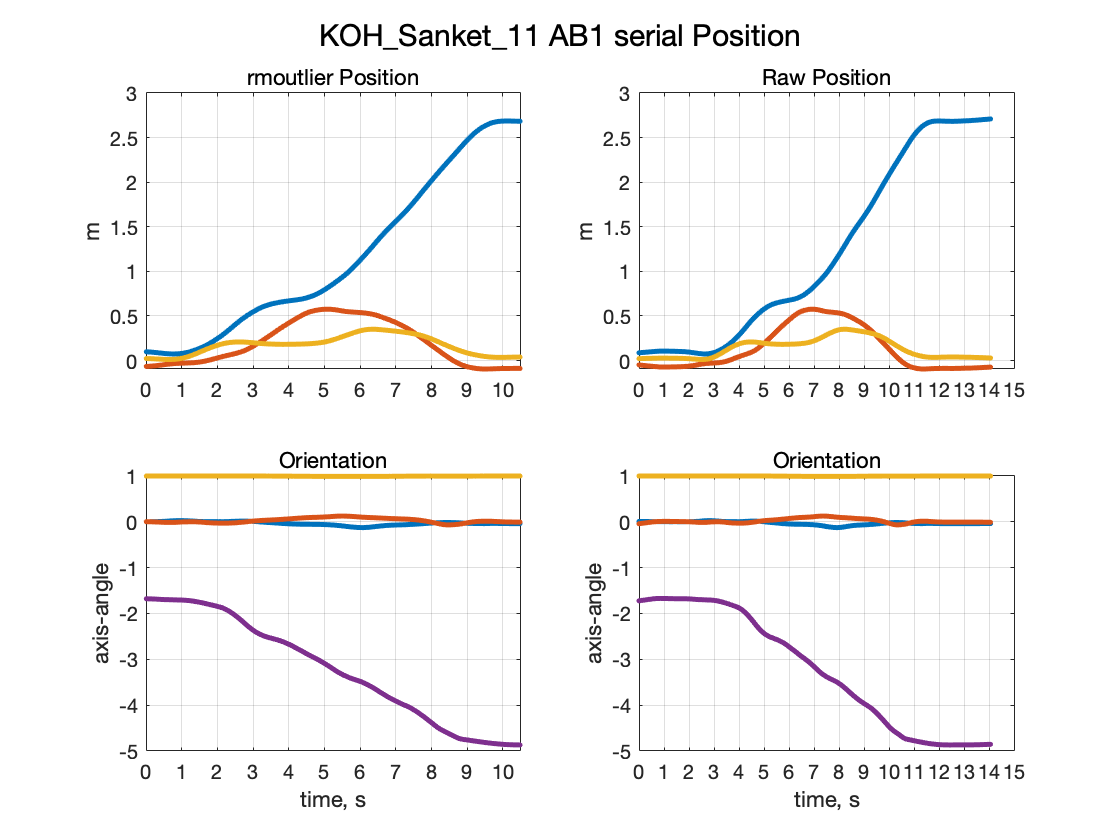

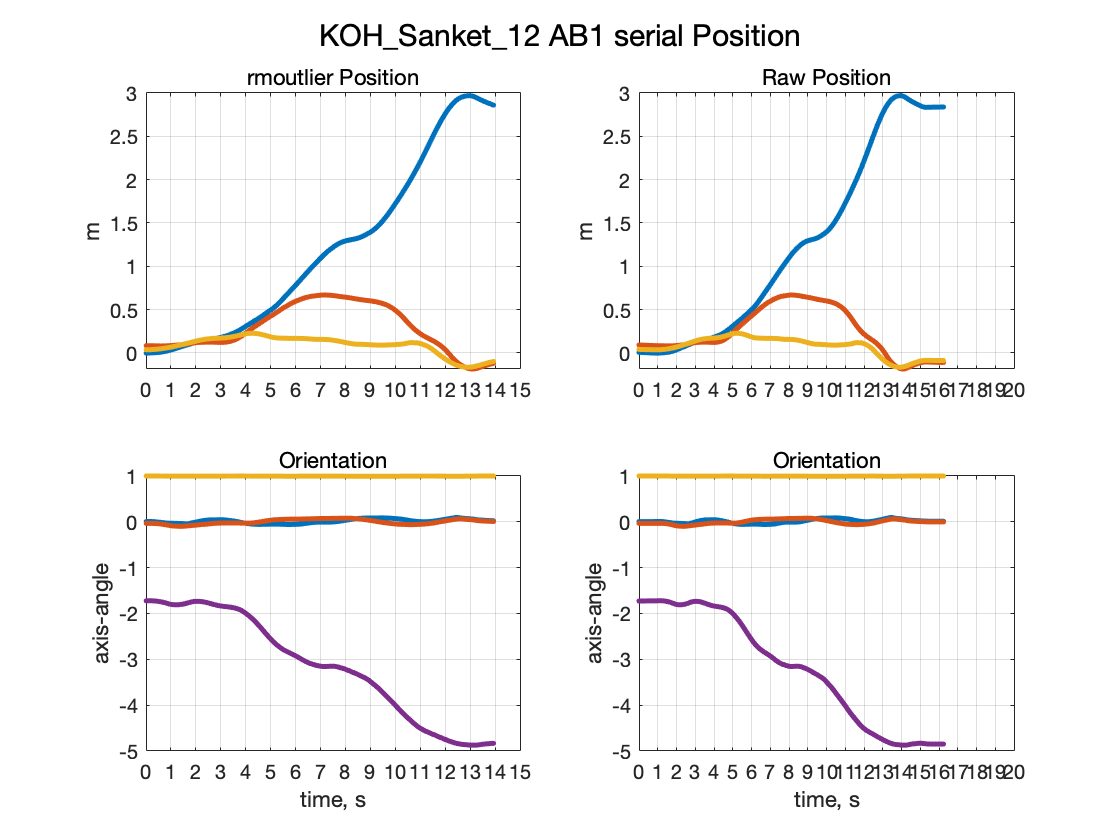

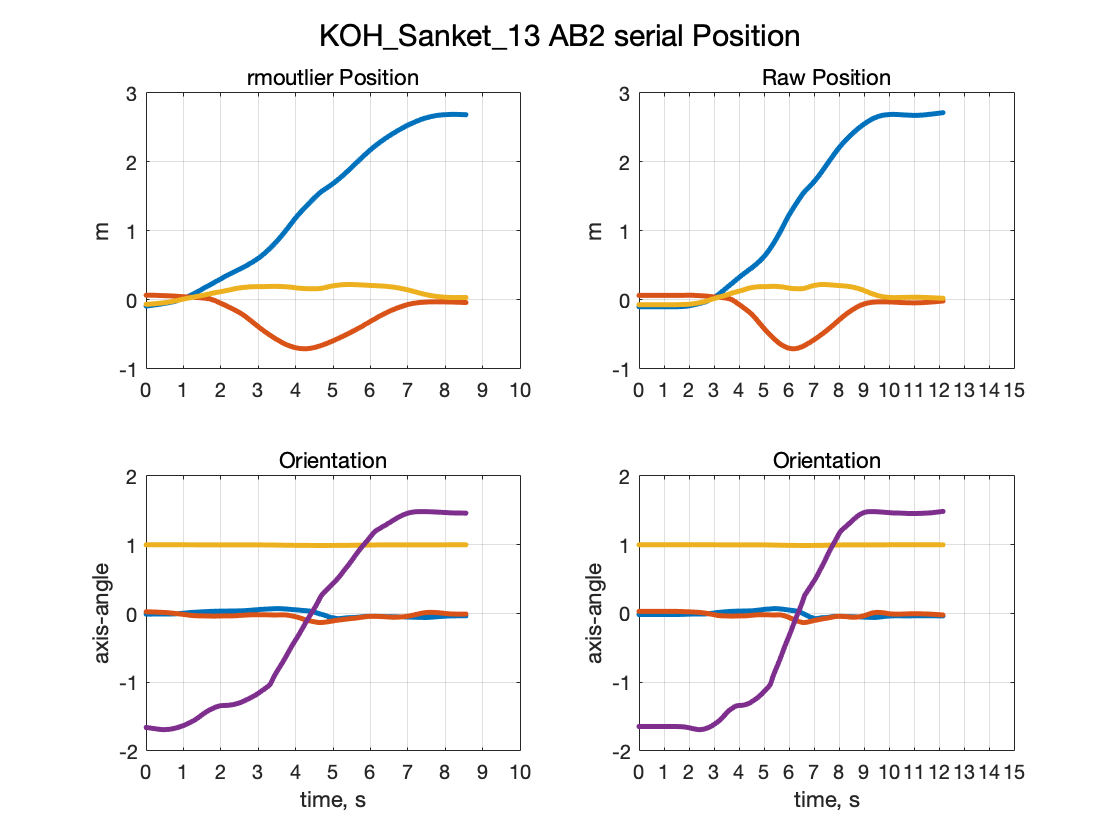

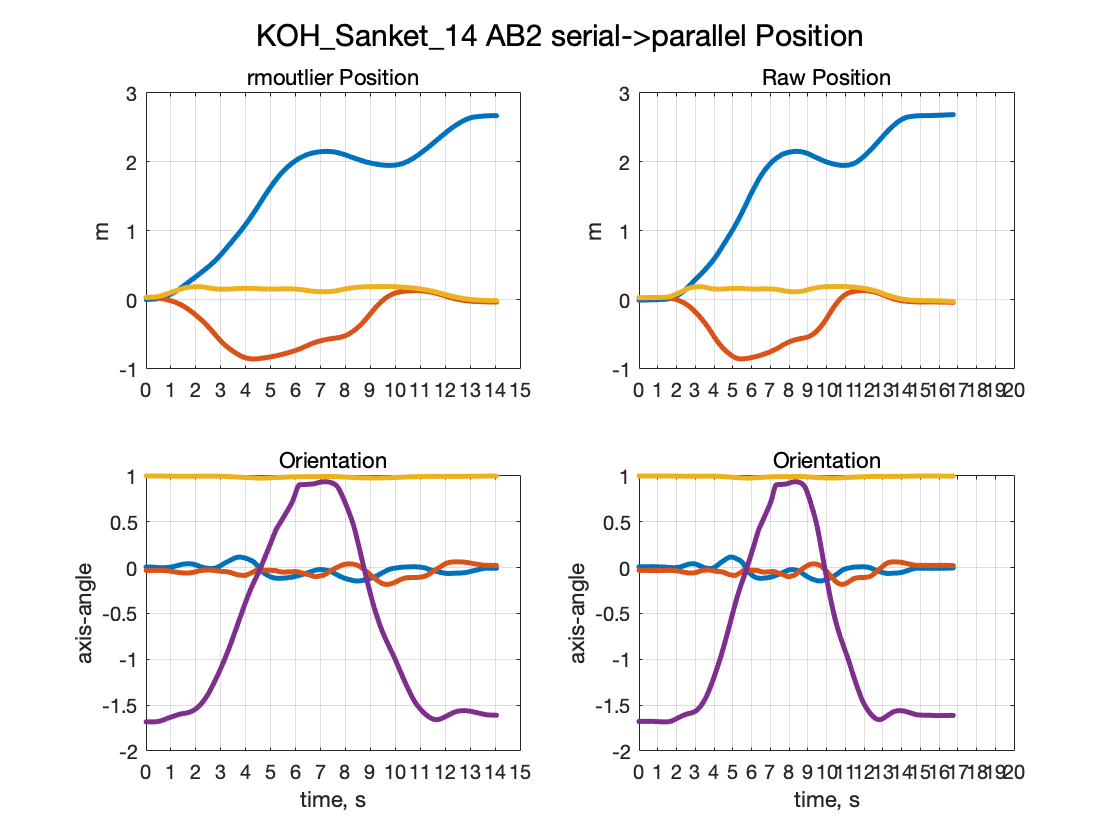

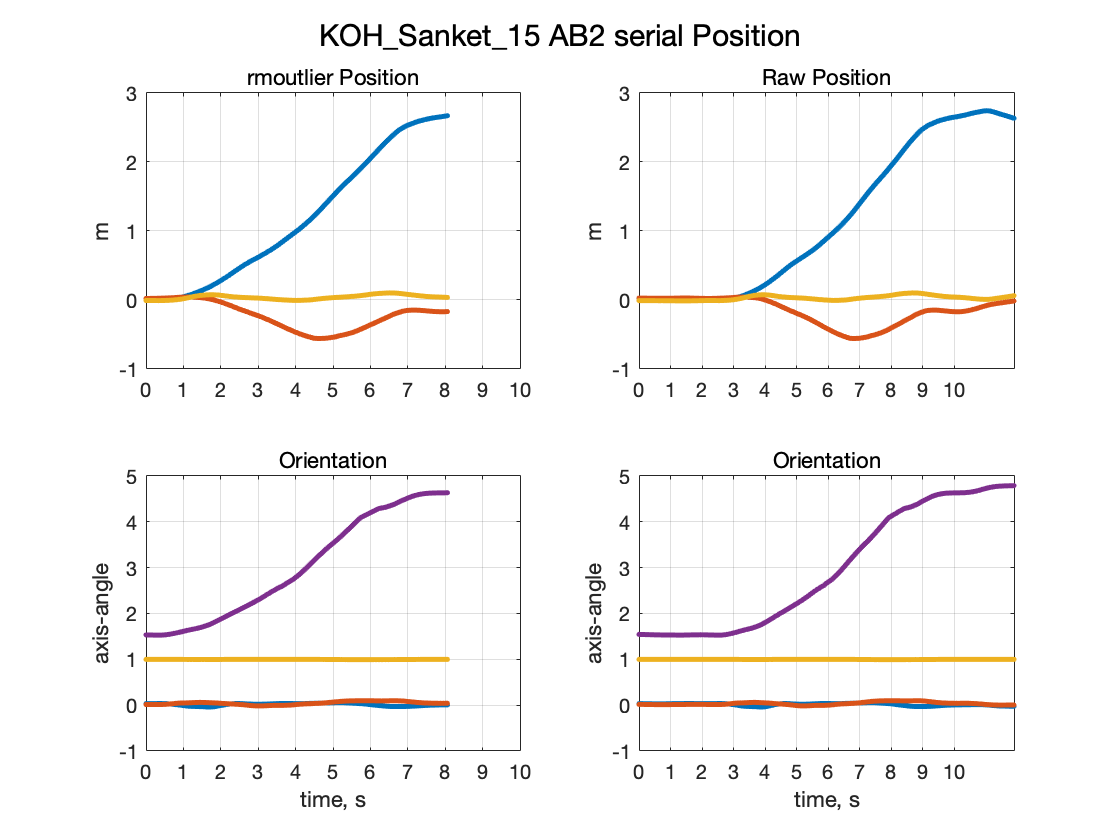

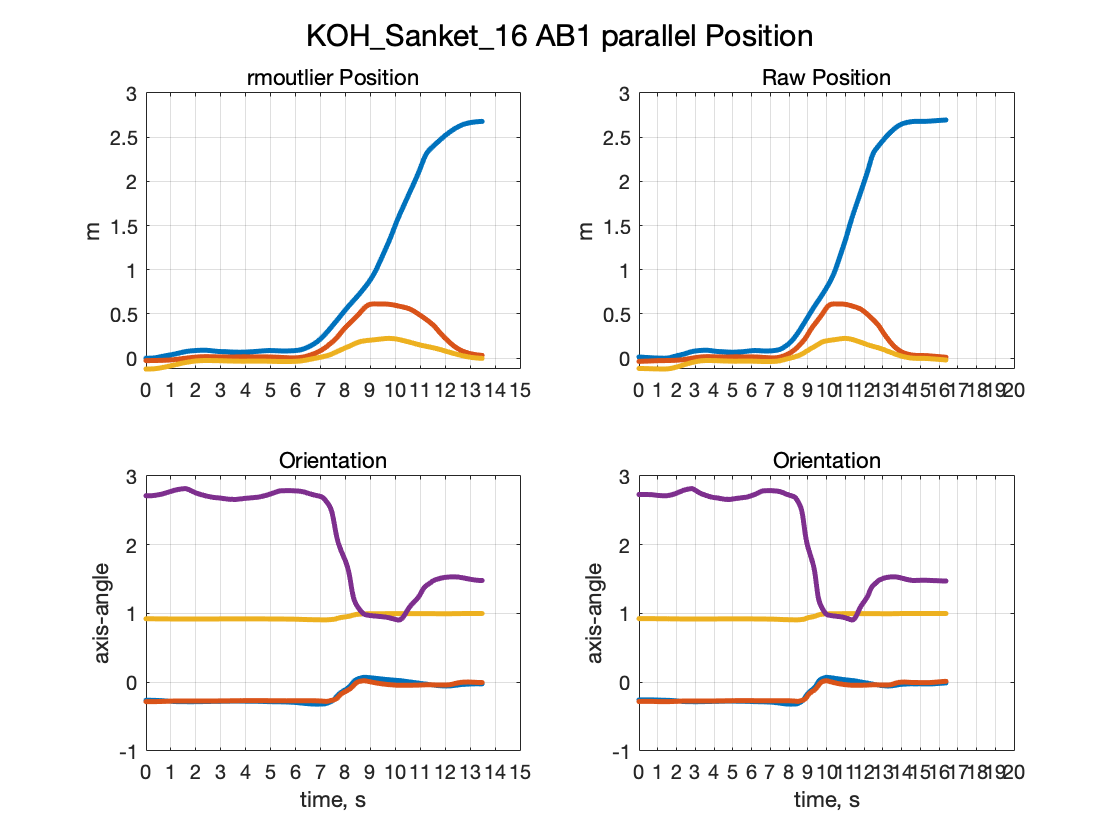

%% Plot a dozen of samples
for i=progress(1:10)
    obs = observations_processed(i);
    obs2 = observations(i);
    
    figure(i+1);
    
    subplot(221)
    plot(obs.pose123.time_steps, obs.pose123.position,'.')
    % plot(obs.pose123.position,'.')
    grid on;
    subtitle('rmoutlier Position')
    ylabel('m')
    xts = xticks;
    xticks(xts(1):xts(end));
%     legend('x','y','z')

    subplot(223)
    % plot(obs.pose123.orientation,'.')
    plot(obs.pose123.time_steps, obs.pose123.orientation,'.')

    grid on;
    subtitle('Orientation')
    xlabel('time, s')
    ylabel('axis-angle')
    xts = xticks;
    xticks(xts(1):xts(end));
%     legend('x','y','z','angle')
    
    
    subplot(222)
    plot(obs2.pose123.time_steps, obs2.pose123.position,'.')
    % plot(obs.pose123.position,'.')
    grid on;
    subtitle('Raw Position')
    ylabel('m')
    xts = xticks;
    xticks(xts(1):xts(end));
%     legend('x','y','z')

    subplot(224)
    % plot(obs.pose123.orientation,'.')
    plot(obs2.pose123.time_steps, obs2.pose123.orientation,'.')

    grid on;
    subtitle('Orientation')
    xlabel('time, s')
    ylabel('axis-angle')
%     legend('x','y','z','angle')
    xts = xticks;
    xticks(xts(1):xts(end));

    sgtitle(sprintf('%s %s %s Position', obs.obs_id, obs.traj_type, obs.motion_type ), ...
            'Interpreter','none');
    
end